# Lab 2: PCA-based Face Recognition

Submission : Blackboard, by 1:30PM on Wednesday, 18 September, 2019

## Dataset

We will use the ORL database, available to download on AT&T’s web site. This database contains photographs showing the faces of 40 people. Each one of them was photographed 10 times. These photos are stored as grayscale images with $112\times92$ pixels. 

In our example, we construct a catalog called `orlfaces`, comprised of people named $s_1, s_2, . . . , s_{40}$, each one of them containing 10 photographs of the person. The data has already been split into a training and testing split, where for each person, we use the first 9 photographs for training and the last photograph for test.

1. Load the training data

% Your code goes here
clc
clear
for m = 1:40
    Path = ['./orl_faces/Train/s',num2str(m)];
    Data = dir(fullfile(Path,'*.pgm'));
    for n = 1:numel(Data)
        ds{n,m} = imread(fullfile(Path,Data(n).name));
    end
end

2. Change each $(d_1, d_2) = (112, 92)$ photograph into a vector

% Your code goes here
dssize = size(ds);
X = [];
for i=1:dssize(2)
    for j=1:dssize(1)
        temp = ds{j,i};
        line = double(reshape(temp,[],1));
        %ds{i,j} = reshape(temp,[],1);
        X = horzcat(X,line);
    end
end


3. Using all the training photographs for the $N$ people in the training dataset, construct a subspace $H$with dimensionality less than or equal to $N$such that this subspace has the maximum dispersion for the $N$ projections. To extract this subspace, use Principal Component Analysis, as described below - 

- Center the data

- Compute the correlation matrix

- Use either the `SVD` or `eig` functions to perform SVD and get the eigenvectors and eigenvalues for the correlation matrix.

- Normalize the eigenvectors by the corresponding eigenvalues.

% Your code goes here

train_mean = mean(X,2);
Xm = X-repmat(train_mean,1,360);

corr = Xm * Xm';
[vector,eigval] = eig(corr);


4. Plot the eigenvalues

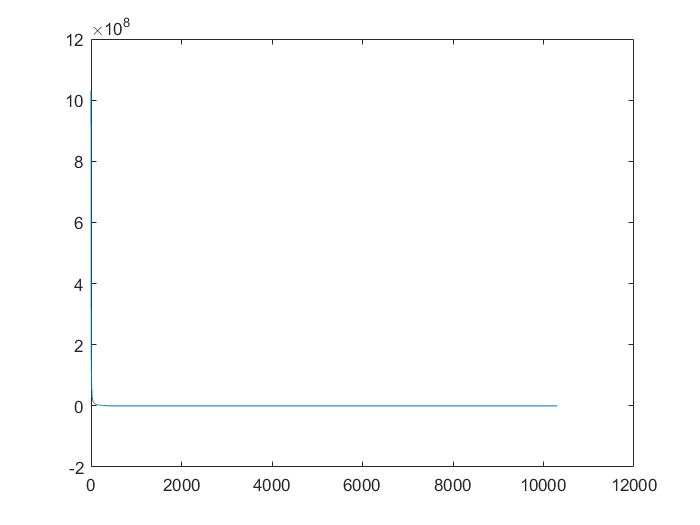

% Your code goes here

eigval_list = diag(eigval);
[eigval_list,index] = sort(eigval_list,'descend');
figure;
plot(eigval_list);

5. Plot the first 3 eigenfaces and the last eigenface (these will be the correctly reshaped eigenvectors)

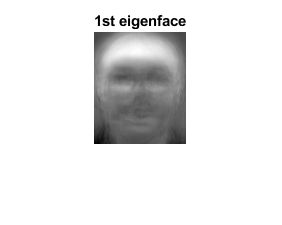

% Your code goes here
f1 = vector(:,index(1));
f1 = reshape(f1,[],92);
figure
imshow(array2mat(f1)),title('1st eigenface');

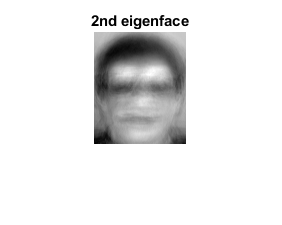

f2 = vector(:,index(2));
f2 = reshape(f2,[],92);
figure
imshow(array2mat(f2)),title('2nd eigenface');

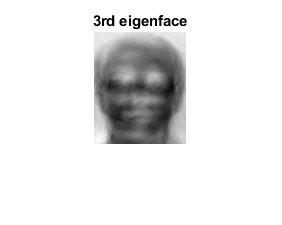

f3 = vector(:,index(3));
f3 = reshape(f3,[],92);
figure
imshow(array2mat(f3)),title('3rd eigenface');

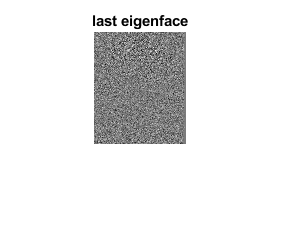

fend = vector(:,index(end));
fend = reshape(fend,[],92);
figure
imshow(array2mat(fend)),title('last eigenface');

6. Pick a face and reconstruct it using $k = {10, 20, 30, 40}$ eigenvectors. Plot all of these reconstructions and compare them. For each value of $k$, plot the original image, reconstructed image, and the difference b/w the original image and reconstruction in each case. Write your observations.

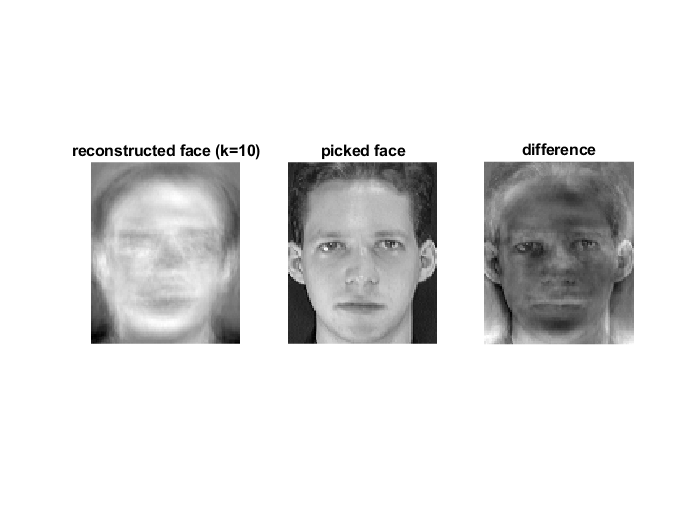

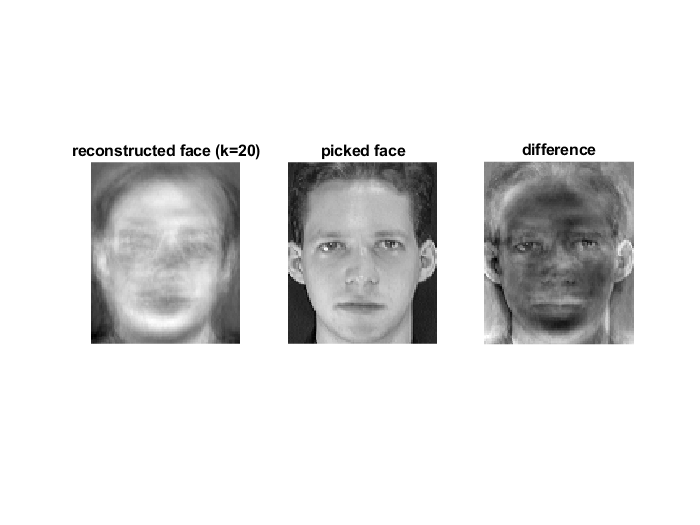

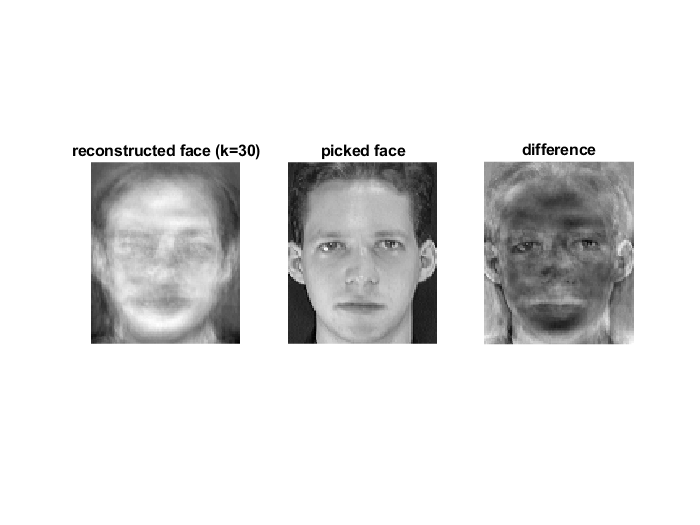

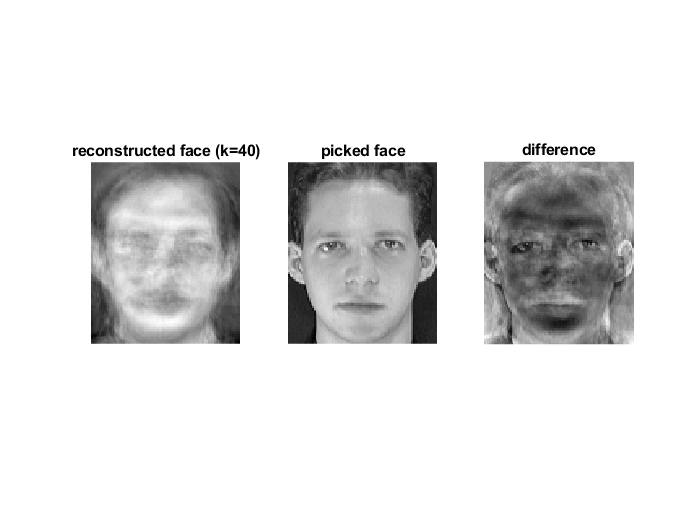

% Your code goes here

%recon = eigenVector'*trainCentered;
picked_face = reshape(double(ds{1,1}),[],1);
k = [10,20,30,40];
for i=1:length(k)
    eigenface = vector(:,index(k(i)):index(1));
    reconstructed_face = eigenface* (eigenface' * picked_face) + train_mean;
    %sum_face = sum(eigenface,2);
    reconstructed_face = reshape(reconstructed_face,[112,92]);
    figure()
    subplot 131
    imshow(array2mat(reconstructed_face));
    title(['reconstructed face (k=',num2str(k(i)),')'])
    subplot 132
    imshow(array2mat(reshape(picked_face,[112,92])));
    title('picked face')
    subplot 133
    imshow(array2mat(reshape(picked_face,[112,92])-reconstructed_face));
    title('difference')
end

7. Load the testing data, and reshape it similar to the training data.

% Your code goes here

for m = 1:40
    Path = ['./orl_faces/Test/s',num2str(m)];
    Data = dir(fullfile(Path,'*.pgm'));
    for n = 1:numel(Data)
        dst{n,m} = imread(fullfile(Path,Data(n).name));
    end
end
dstsize = size(dst);
Xt = [];
for i=1:dstsize(2)
    temp = dst{1,i};
    line = double(reshape(temp,[],1));
    Xt = horzcat(Xt,line);
end

%
Xtm = Xt - repmat(train_mean,1,40);

8. For each photograph in the testing dataset, you will implement a classifier to predict the identity of the person. To do this, follow these steps - 

- Determine the projection of each test photo onto $H$ with different dimensionalities $d = {10, 20, 30, 40}$

- Compare the distance of this projection to the projections of all images in the training data.

- For each test photo's projection, find the closest category of projection in the training data.

% Your code goes here
eigenface_10 = vector(:,index(10):index(1));
eigenface_20 = vector(:,index(20):index(1));
eigenface_30 = vector(:,index(30):index(1));
eigenface_40 = vector(:,index(40):index(1));
dist=[];





test_proj = eigenface_10'*Xtm;
train_proj = eigenface_10'*Xm;
for i = 1:width(test_proj)
    for j = 1:width(train_proj)
        dist(i,j) = sqrt(sum((test_proj(:,i)-train_proj(:,j)).^2));
    end
end
[min_dist,index_dist] = min(dist,[],2);
correct=0;
for i=1:40
    category(1,i) = ceil(index_dist(i)/9);
    category(2,i) = index_dist(i)-(category(1,i)-1)*9;
    disp(['For test img s',num2str(i),', the closest in train set is ',num2str(category(2,i)),'.pgm in s',num2str(category(1,i))])
%     if i==category(1,i)
%         correct=correct+1;
%     end
end

For test img s1, the closest in train set is 8.pgm in s1
For test img s2, the closest in train set is 8.pgm in s2
For test img s3, the closest in train set is 9.pgm in s3
For test img s4, the closest in train set is 5.pgm in s4
For test img s5, the closest in train set is 6.pgm in s18
For test img s6, the closest in train set is 4.pgm in s6
For test img s7, the closest in train set is 5.pgm in s7
For test img s8, the closest in train set is 3.pgm in s8
For test img s9, the closest in train set is 5.pgm in s9
For test img s10, the closest in train set is 4.pgm in s38
For test img s11, the closest in train set is 1.pgm in s11
For test img s12, the closest in train set is 9.pgm in s12
For test img s13, the closest in train set is 5.pgm in s13
For test img s14, the closest in train set is 6.pgm in s14
For test img s15, the closest in train set is 5.pgm in s15
For test img s16, the closest in train set is 2.pgm in s16
For test img s17, the closest in train set is 7.pgm in s17
For test img s

test_proj = eigenface_20'*Xtm;
train_proj = eigenface_20'*Xm;
for i = 1:width(test_proj)
    for j = 1:width(train_proj)
        dist(i,j) = sqrt(sum((test_proj(:,i)-train_proj(:,j)).^2));
    end
end
[min_dist,index_dist] = min(dist,[],2);
correct=0;
for i=1:40
    category(1,i) = ceil(index_dist(i)/9);
    category(2,i) = index_dist(i)-(category(1,i)-1)*9;
    disp(['For test img s',num2str(i),', the closest in train set is ',num2str(category(2,i)),'.pgm in s',num2str(category(1,i))])
%     if i==category(1,i)
%         correct=correct+1;
%     end
end

For test img s1, the closest in train set is 8.pgm in s1
For test img s2, the closest in train set is 8.pgm in s2
For test img s3, the closest in train set is 9.pgm in s3
For test img s4, the closest in train set is 5.pgm in s4
For test img s5, the closest in train set is 5.pgm in s40
For test img s6, the closest in train set is 4.pgm in s6
For test img s7, the closest in train set is 5.pgm in s7
For test img s8, the closest in train set is 3.pgm in s8
For test img s9, the closest in train set is 5.pgm in s9
For test img s10, the closest in train set is 4.pgm in s38
For test img s11, the closest in train set is 1.pgm in s11
For test img s12, the closest in train set is 9.pgm in s12
For test img s13, the closest in train set is 5.pgm in s13
For test img s14, the closest in train set is 6.pgm in s14
For test img s15, the closest in train set is 2.pgm in s15
For test img s16, the closest in train set is 2.pgm in s16
For test img s17, the closest in train set is 7.pgm in s17
For test img s


test_proj = eigenface_30'*Xtm;
train_proj = eigenface_30'*Xm;
for i = 1:width(test_proj)
    for j = 1:width(train_proj)
        dist(i,j) = sqrt(sum((test_proj(:,i)-train_proj(:,j)).^2));
    end
end
[min_dist,index_dist] = min(dist,[],2);
correct=0;
for i=1:40
    category(1,i) = ceil(index_dist(i)/9);
    category(2,i) = index_dist(i)-(category(1,i)-1)*9;
    disp(['For test img s',num2str(i),', the closest in train set is ',num2str(category(2,i)),'.pgm in s',num2str(category(1,i))])
%     if i==category(1,i)
%         correct=correct+1;
%     end
end

For test img s1, the closest in train set is 5.pgm in s1
For test img s2, the closest in train set is 8.pgm in s2
For test img s3, the closest in train set is 9.pgm in s3
For test img s4, the closest in train set is 5.pgm in s4
For test img s5, the closest in train set is 5.pgm in s40
For test img s6, the closest in train set is 4.pgm in s6
For test img s7, the closest in train set is 5.pgm in s7
For test img s8, the closest in train set is 3.pgm in s8
For test img s9, the closest in train set is 5.pgm in s9
For test img s10, the closest in train set is 4.pgm in s38
For test img s11, the closest in train set is 1.pgm in s11
For test img s12, the closest in train set is 9.pgm in s12
For test img s13, the closest in train set is 5.pgm in s13
For test img s14, the closest in train set is 9.pgm in s14
For test img s15, the closest in train set is 2.pgm in s15
For test img s16, the closest in train set is 2.pgm in s16
For test img s17, the closest in train set is 7.pgm in s17
For test img s


test_proj = eigenface_40'*Xtm;
train_proj = eigenface_40'*Xm;
for i = 1:width(test_proj)
    for j = 1:width(train_proj)
        dist(i,j) = sqrt(sum((test_proj(:,i)-train_proj(:,j)).^2));
    end
end
[min_dist,index_dist] = min(dist,[],2);
correct=0;
for i=1:40
    category(1,i) = ceil(index_dist(i)/9);
    category(2,i) = index_dist(i)-(category(1,i)-1)*9;
    disp(['For test img s',num2str(i),', the closest in train set is ',num2str(category(2,i)),'.pgm in s',num2str(category(1,i))])
%     if i==category(1,i)
%         correct=correct+1;
%     end
end

For test img s1, the closest in train set is 5.pgm in s1
For test img s2, the closest in train set is 7.pgm in s2
For test img s3, the closest in train set is 9.pgm in s3
For test img s4, the closest in train set is 5.pgm in s4
For test img s5, the closest in train set is 5.pgm in s40
For test img s6, the closest in train set is 4.pgm in s6
For test img s7, the closest in train set is 5.pgm in s7
For test img s8, the closest in train set is 3.pgm in s8
For test img s9, the closest in train set is 5.pgm in s9
For test img s10, the closest in train set is 4.pgm in s38
For test img s11, the closest in train set is 1.pgm in s11
For test img s12, the closest in train set is 9.pgm in s12
For test img s13, the closest in train set is 5.pgm in s13
For test img s14, the closest in train set is 9.pgm in s14
For test img s15, the closest in train set is 2.pgm in s15
For test img s16, the closest in train set is 3.pgm in s16
For test img s17, the closest in train set is 7.pgm in s17
For test img s

9. Show the closest image in the training dataset for the $s_1$ test example.

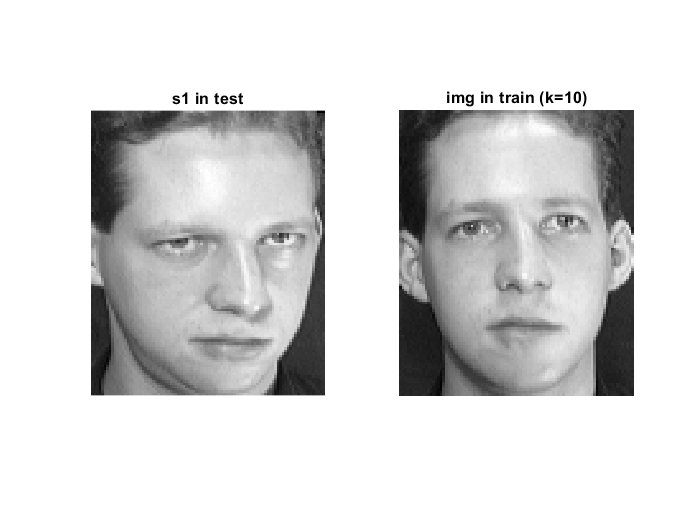

test_proj = eigenface_10'*Xtm;
train_proj = eigenface_10'*Xm;
for i = 1:width(test_proj)
    for j = 1:width(train_proj)
        dist(i,j) = sqrt(sum((test_proj(:,i)-train_proj(:,j)).^2));
    end
end
[min_dist,index_dist] = min(dist,[],2);
correct=0;
for i=1:40
    category(1,i) = ceil(index_dist(i)/9);
    category(2,i) = index_dist(i)-(category(1,i)-1)*9;
end
figure
subplot 121
imshow(array2mat(reshape(dst{1,1},[],92))),title('s1 in test');
subplot 122
imshow(array2mat(reshape(ds{category(2,1),category(1,1)},[],92))),title('img in train (k=10)');

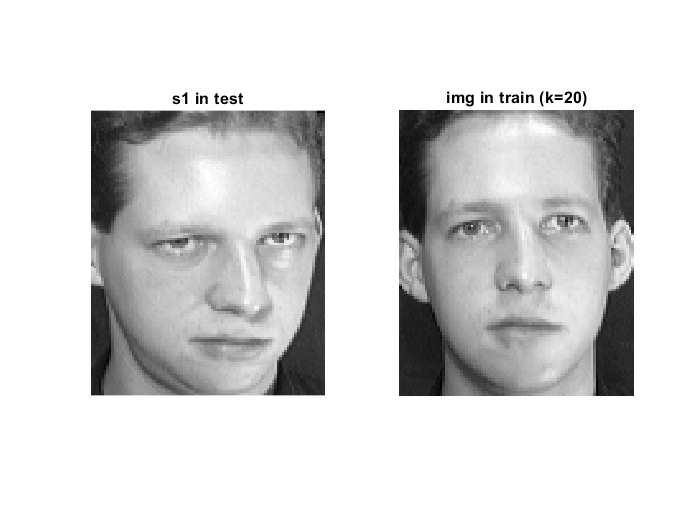

test_proj = eigenface_20'*Xtm;
train_proj = eigenface_20'*Xm;
for i = 1:width(test_proj)
    for j = 1:width(train_proj)
        dist(i,j) = sqrt(sum((test_proj(:,i)-train_proj(:,j)).^2));
    end
end
[min_dist,index_dist] = min(dist,[],2);
correct=0;
for i=1:40
    category(1,i) = ceil(index_dist(i)/9);
    category(2,i) = index_dist(i)-(category(1,i)-1)*9;
end
figure
subplot 121
imshow(array2mat(reshape(dst{1,1},[],92))),title('s1 in test');
subplot 122
imshow(array2mat(reshape(ds{category(2,1),category(1,1)},[],92))),title('img in train (k=20)');

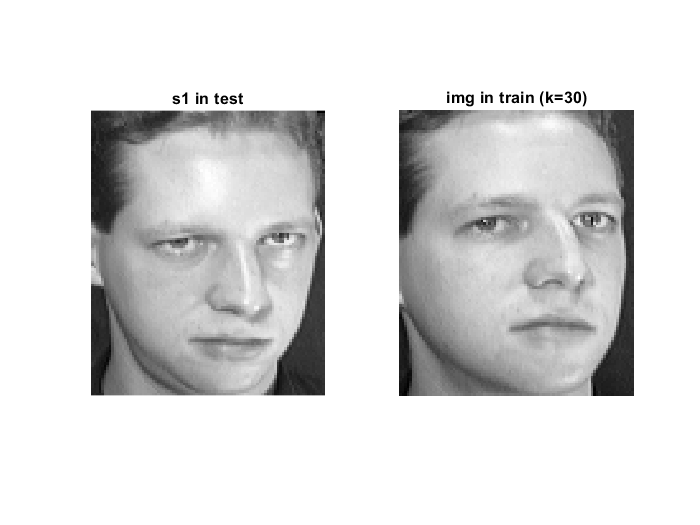


test_proj = eigenface_30'*Xtm;
train_proj = eigenface_30'*Xm;
for i = 1:width(test_proj)
    for j = 1:width(train_proj)
        dist(i,j) = sqrt(sum((test_proj(:,i)-train_proj(:,j)).^2));
    end
end
[min_dist,index_dist] = min(dist,[],2);
correct=0;
for i=1:40
    category(1,i) = ceil(index_dist(i)/9);
    category(2,i) = index_dist(i)-(category(1,i)-1)*9;
end
figure
subplot 121
imshow(array2mat(reshape(dst{1,1},[],92))),title('s1 in test');
subplot 122
imshow(array2mat(reshape(ds{category(2,1),category(1,1)},[],92))),title('img in train (k=30)');

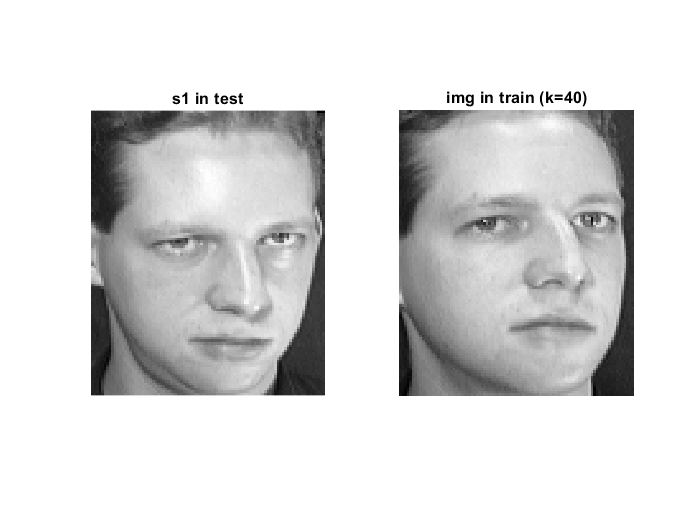


test_proj = eigenface_40'*Xtm;
train_proj = eigenface_40'*Xm;
for i = 1:width(test_proj)
    for j = 1:width(train_proj)
        dist(i,j) = sqrt(sum((test_proj(:,i)-train_proj(:,j)).^2));
    end
end
[min_dist,index_dist] = min(dist,[],2);
correct=0;
for i=1:40
    category(1,i) = ceil(index_dist(i)/9);
    category(2,i) = index_dist(i)-(category(1,i)-1)*9;
end
figure
subplot 121
imshow(array2mat(reshape(dst{1,1},[],92))),title('s1 in test');
subplot 122
imshow(array2mat(reshape(ds{category(2,1),category(1,1)},[],92))),title('img in train (k=40)');